
clc

run_1 = readtable("BM_2023/Enzo/Enzo_12_09_23_AM.csv");
run_2 = readtable("BM_2023/Enzo/Enzo_12_09_2023_PM.csv");

speed_1 = table2array(run_1(:,5));
speed_2 = table2array(run_2(:,5));

power_1 = table2array(run_1(:,6));
power_2 = table2array(run_2(:,6));

cadence_1 = table2array(run_1(:,3));
cadence_2 = table2array(run_2(:,3));

time_1 = (1:size(power_1))';
time_2 = (1:size(power_2))';


## Data Visualization

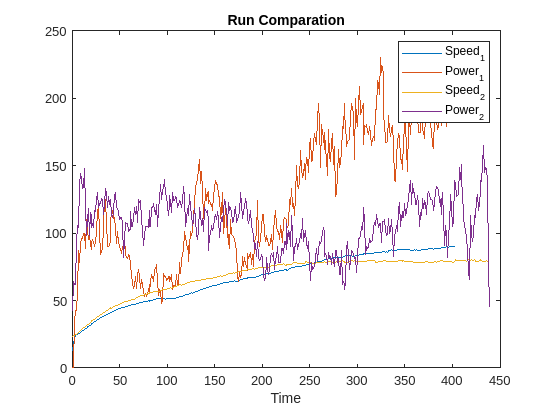

figure
plot(time_1,speed_1,time_1,power_1);
title("Run Comparation");
xlabel("Time");
hold on
plot(time_2,speed_2,time_2,power_2);
legend("Speed_1","Power_1","Speed_2","Power_2");
hold off